clc
clear all
close all
A = [4/3 -2/3; 1 0];
B = [1 0]';
C = [-2/3 1];
D= 0;
Q = C'*C + 0.001*eye(2,2);
R = 0.001;

N = 22;
x0= [10 10]';
x([1 2],1) = x0;

[K_inf,S,e] = dlqr(A,B,Q,R)

K_inf =     0.6683   -0.6660


S =     1.0041   -0.6671
   -0.6671    1.0014


e =     0.6640
    0.0010


K_inf = -K_inf

K_inf =    -0.6683    0.6660


K = optimal gain matrix `K`

e = closed-loop eigenvalues `e = eig(A-B*K)`

S = infinite horizon solution *S* of the associated discrete-time Riccati equation

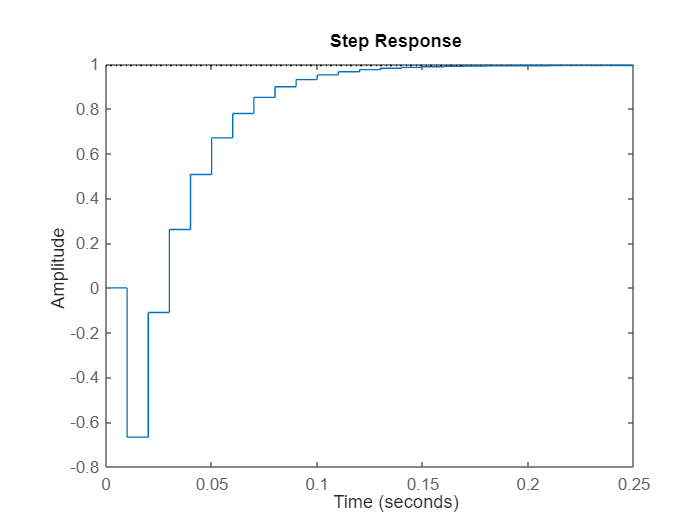

sys = ss(A+B*K_inf,B,C,D,0.01);
step(sys)

Cost of the infinite horizon:

u(1) = K_inf*x0;

for k=2:1000
    x(:,k)= A*x(:,k-1)+B*u(k-1);
    u(k) = K_inf*x(:,k);
end

V_inf = sum(sum((x'*Q*x + x'*K_inf'*R*K_inf*x),1),2);